clear; clc; close all

## Manual PID Tuning

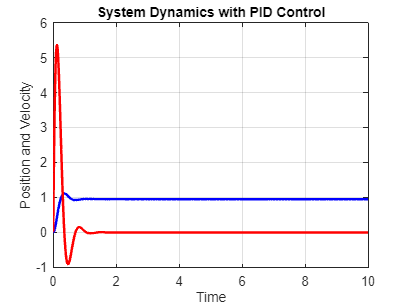

% Defining System Parameters
dynamics_params.mass = 1.0;                 % Mass of the object
dynamics_params.spring_constant = 5.0;      % Spring constant of the spring
dynamics_params.damping_coefficient = 0.1;  % Damping coefficient of the damper

% Initialize PID gains
gains = [-100; -0.001; -10];

% Initial state [position; velocity; integral]
initial_state = [0; 0; 0];

% Desired state [desired_position; desired_velocity]
desired_state = [1; 0];

% Time span for simulation
tspan = [0, 10];  % Start time and end time


% Use numerical integration (ode45) to simulate the system dynamics with PID control
[t, y] = ode45(@(t, y) dynamics(t, y, gains, dynamics_params, desired_state), tspan, initial_state);

% Extract position and velocity for plotting
position = y(:, 1);
velocity = y(:, 2);

% Plot the results
figure;
plot(t, position, 'b', 'LineWidth', 2);
hold on;
plot(t, velocity, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Position and Velocity');
title('System Dynamics with PID Control');
grid on;


cost_manual = cost(gains,desired_state,initial_state,dynamics_params,tspan,ones(2))

cost_manual = 256.6750

## PID Gain Optimisation - ODE45

% interior point
options = optimoptions("fmincon","Display","iter",...
    "Algorithm","interior-point",...
    "EnableFeasibilityMode",true,...
    "SubproblemAlgorithm","cg");
gains_interiorP = fmincon(@(gains)cost(gains,desired_state,initial_state,dynamics_params,tspan,ones(2)),[-100;-0.01;-10],[],[],[],[],[],[],@(gains)DynamicConstODE(gains,desired_state,initial_state,dynamics_params,tspan),options)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       4    2.566785e+02    4.757e-02    2.880e+01
    1       8    2.330276e+02    4.054e-02    1.783e+01    1.732e+00
    2      12    2.176431e+02    2.905e-02    1.033e+01    3.255e+00
    3      16    2.094914e+02    1.023e-02    1.048e+01    8.809e+00
    4      20    1.585707e+02    2.602e-03    5.067e+00    8.363e+00
    5      24    1.300698e+02    2.894e-04    1.402e+00    4.759e+00
    6      28    1.277862e+02    3.107e-05    3.385e+00    1.898e+00
    7      32    1.268010e+02    2.074e-06    3.233e+00    1.674e-01
    8      36    1.214482e+02    7.541e-07    3.484e+00    1.142e+00
    9      40    1.012287e+02    2.028e-04    3.348e+00    4.649e+00
   10      44    5.698983e+01    2.978e-03    1.974e+00    1.388e+01
   11      48    3.492007e+01    1.239e-04    9.217e-01    1.317e+01
   12      52    2.504024e+01    2.150e-03    3

gains_interiorP =   -70.5845
   -5.1603
  -68.4177


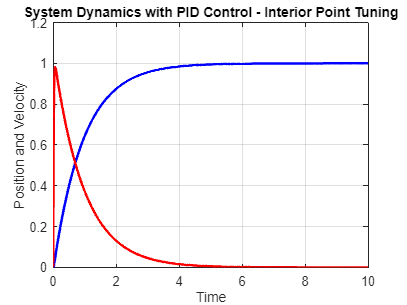


% Use numerical integration (ode45) to simulate the system dynamics with PID control
[t, y] = ode45(@(t, y) dynamics(t, y, gains_interiorP, dynamics_params, desired_state), tspan, initial_state);

% Extract position and velocity for plotting
position = y(:, 1);
velocity = y(:, 2);

% Plot the results
figure;
plot(t, position, 'b', 'LineWidth', 2);
hold on;
plot(t, velocity, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Position and Velocity');
title('System Dynamics with PID Control - Interior Point Tuning');
grid on;


cost_interiorP = cost(gains_interiorP,desired_state,initial_state,dynamics_params,tspan,ones(2))

cost_interiorP = 22.3014

## PID Gain Optimisation - Genetic Algorithm

% Define the GA options
ga_options = optimoptions('ga', 'Display', 'iter', 'PopulationSize', 20, 'MaxGenerations', 25);

% Set the lower and upper bounds for the PID gains
ub = [-10, -0.0005, -1]; % Lower bounds for Kp, Ki, and Kd
lb = [-200, -0.06, -20]; % Upper bounds for Kp, Ki, and Kd

% Perform the optimization using GA
gains_ga = ga(@(gains) cost(gains, desired_state, initial_state, dynamics_params, tspan, ones(2)), 3, [], [], [], [], [], [], @(gains) DynamicConstODE(gains, desired_state, initial_state, dynamics_params, tspan), ga_options)


Single objective optimization:
3 Variable(s)
5 Nonlinear equality constraint(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationgaussian

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1            516       53848.4         72.9      0
    2           1012       236.707          3.1      0
    3           1508       23.3404      0.02562      0
    4           2004       23.3549    3.641e-05      0
Optimization finished: average change in the fitness value less than options.FunctionTolerance and constraint violation is less than options.ConstraintTolerance.


gains_ga =    -4.0397   -6.0531   -5.5127


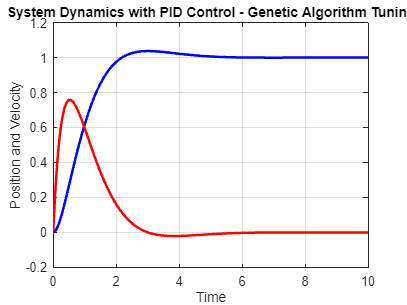



% Use numerical integration (ode45) to simulate the system dynamics with PID control
[t, y] = ode45(@(t, y) dynamics(t, y, gains_ga, dynamics_params, desired_state), tspan, initial_state);

% Extract position and velocity for plotting
position = y(:, 1);
velocity = y(:, 2);

% Plot the results
figure;
plot(t, position, 'b', 'LineWidth', 2);
hold on;
plot(t, velocity, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Position and Velocity');
title('System Dynamics with PID Control - Genetic Algorithm Tuning');
grid on;


cost_ga = cost(gains_ga,desired_state,initial_state,dynamics_params,tspan,ones(2))

cost_ga = 23.3549

## PID Gain Optimisation - Particle Swarm

% Define the GA options
ps_options = optimoptions('particleswarm', 'Display', 'iter', 'SwarmSize', 100);

% Set the lower and upper bounds for the PID gains
ub = [-10, -0.0005, -1]; % Lower bounds for Kp, Ki, and Kd
lb = [-200, -0.06, -20]; % Upper bounds for Kp, Ki, and Kd

% Perform the optimization using GA
gains_ps = particleswarm(@(gains) cost(gains, desired_state, initial_state, dynamics_params, tspan, ones(2)), 3, [], [], ps_options)


                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0             100           27.99             NaN        0
    1             200           27.99             Inf        0
    2             300           27.99             Inf        1
    3             400           27.99      2.952e+231        2
    4             500           27.99      4.453e+261        3
    5             600           27.99      2.867e+207        4
    6             700           27.99      3.066e+145        5
    7             800           27.99             Inf        6
    8             900           27.99             Inf        7
    9            1000           27.99             Inf        8
   10            1100           27.14             Inf        0
   11            1200           23.31             Inf        0
   12            1300            22.7             Inf        0
   13            1400            22.7           

gains_ps =  -520.3897   -4.7920 -517.6774


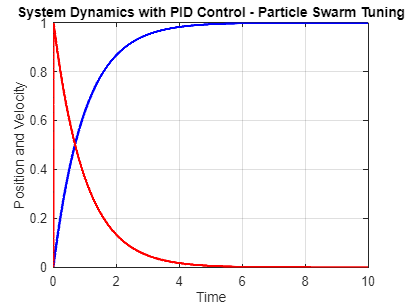


% Use numerical integration (ode45) to simulate the system dynamics with PID control
[t, y] = ode45(@(t, y) dynamics(t, y, gains_ps, dynamics_params, desired_state), tspan, initial_state);

% Extract position and velocity for plotting
position = y(:, 1);
velocity = y(:, 2);

% Plot the results
figure;
plot(t, position, 'b', 'LineWidth', 2);
hold on;
plot(t, velocity, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Position and Velocity');
title('System Dynamics with PID Control - Particle Swarm Tuning');
grid on;


cost_ps = cost(gains_ps,desired_state,initial_state,dynamics_params,tspan,ones(2))

cost_ps = 22.0218

## PID Gain Optimisation - with Pseudospectral Formulation

N = 21;

init = zeros(5, N+1);
% init(3,1) = -gains_ps(1);
% init(4,1) = -gains_ps(2);
% init(5,1) = -gains_ps(3);

options = optimoptions('fmincon','Display','iter','MaxFunctionEvaluations',1e5,'Algorithm','sqp',"EnableFeasibilityMode",true,'MaxIterations',5e3);

tf = 20; 
desired_state = [1; 0];
initial_state = [0; 0];
Q = ones(2);

[Z,~,flg] = fmincon(@(Z)cost_pseudospectral(Z,desired_state,Q,N,tf),init,[],[],[],[],[],[],@(Z)NonLinCon_PseudoSpectral(Z,initial_state,desired_state,dynamics_params,N,tf),options);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         111    1.997732e+01     1.000e+00     1.000e+00     0.000e+00     2.984e+00  
    1         225    1.324755e+01     6.570e-01     3.430e-01     9.983e-01     1.949e+02  
    2         339    8.585449e+00     9.722e-01     3.430e-01     8.839e-01     1.662e+02  
    3         454    6.249061e+00     1.029e+00     2.401e-01     5.479e-01     1.927e+02  
    4         569    4.536904e+00     1.072e+00     2.401e-01     3.987e-01     1.949e+02  
    5         684    3.494047e+00     1.027e+00     2.401e-01     3.549e-01     2.498e+02  
    6         797    2.528957e+00     9.795e-01     4.900e-01     5.700e-01     3.530e+02  
    7         908    2.374054e+00     1.401e-01     1.000e+00     9.830e-01     4.253e+02  
    8        1020    2.476685e+00     1.405e-01     7.000e-01     1.248e+00     4.

gains_psuedospectral = Z(3:5,1).'

gains_psuedospectral =    -1.2300    2.1017    1.4704


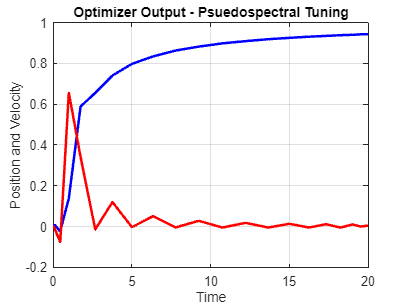


[nodes,~] = clencurt(N);
tspan_ = ((flip(nodes)+1)/2).*tf;

% Extract position and velocity for plotting
position = Z(1, :);
velocity = Z(2, :);

% Plot the results
figure;
plot(tspan_, position, 'b', 'LineWidth', 2);
hold on;
plot(tspan_, velocity, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Position and Velocity');
title('Optimizer Output - Psuedospectral Tuning');
grid on;

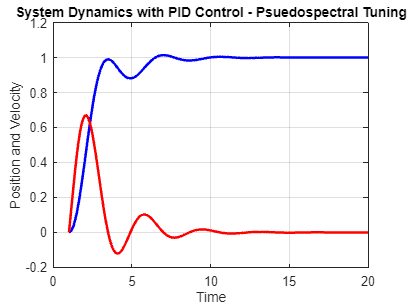


% Use numerical integration (ode45) to simulate the system dynamics with PID control
[t, y] = ode45(@(t, y) dynamics(t, y, -gains_psuedospectral, dynamics_params, desired_state), 1:0.1:tf, [0; 0; 0]);

% Extract position and velocity for plotting
position = y(:, 1);
velocity = y(:, 2);

% Plot the results
figure;
plot(t, position, 'b', 'LineWidth', 2);
hold on;
plot(t, velocity, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Position and Velocity');
title('System Dynamics with PID Control - Psuedospectral Tuning');
grid on;


cost_pseudospec = cost(-gains_psuedospectral,desired_state,[0; 0; 0],dynamics_params,tspan,ones(2))

cost_pseudospec = 42.8433

## Non-Linear Constraint for Pseudospectral Optimisation

function [c,ceq] = NonLinCon_PseudoSpectral(Z,initial_state,desired_state,dynamics_params,N,tf)
    
    state = Z(1:2,:);
    gains = Z(3:5,1);

    Kp = gains(1);
    Ki = gains(2);
    Kd = gains(3);

    c =[];
    % c(1) = Kp - 200;
    % c(2) = Ki - 0.06;
    % c(3) = Kd - 20;
    % c(4) = 10 - Kp;
    % c(5) = 0.0005 - Ki;
    % c(6) = 1 - Kd;

    % Use Guass-Quadrature integration to simulate system dynamics with PID
    error = desired_state(1,:) - state(1,:);
    integral = zeros(size(error));
    integral(:,1) = error(:,1);

    velocity_error = desired_state(2,:) - state(2,:);

    % [~,wk] = clencurt(N);
    wk = zeros(N+1);
    wk(1) = 0;
    
    [nodes,~] = clencurt(N);
    tspan_ = ((flip(nodes)+1)/2).*tf;
    for i = 1:N
        [~,weights] = clencurt(i);
        wk(i+1,1:i+1) = weights';
        wk(i+1,:) = wk(i+1,:)*tspan_(i+1);
    end

    % for i = 2:size(state,2)
    %     integral(:,i) = integral(:,i-1) + wk(i)*error(:,i);
    % end

    for i = 1:1 % Detemines which variables error
        for j = 2:size(state,2) % Determines which node it is being calculated at
            integral(i,j) = sum(wk(j,:)*error(:,j));
        end
    end

    D = -DCPeyret(N+1);

    % Unpack state variables
    position = state(1,:);
    velocity = state(2,:);

    % Unpack dynamics parameters from the struct
    mass = dynamics_params.mass;
    spring_constant = dynamics_params.spring_constant;
    damping_coefficient = dynamics_params.damping_coefficient;

    input = Kp*error + Ki*integral + Kd*velocity_error;

    % Compute the acceleration (second derivative of position)
    acceleration = (input - damping_coefficient * velocity - spring_constant * position) / mass;

    c_dynamics = ((2/tf)*D*state.').' - ([velocity; acceleration]);
    reshape(c_dynamics, [], 1);

    ceq_init = state(:,1) - initial_state;
    ceq_des = state(:,end) - desired_state;

    ceq = vertcat(reshape(ceq_init,[2,1]),reshape(ceq_des,[2,1]),reshape(c_dynamics, [], 1));
end


### Cost Pseudospectral Optimisation

function J = cost_pseudospectral(Z,desired_state,Q,N,tf)

    [~,wk] = clencurt(N);
    
    state = Z(1:2,:);
    J = 0;
    for i = 1:N
        J = J + wk(i)*((state(:,i)-desired_state).'*Q*(state(:,i)-desired_state));
    end
    J = J*(tf/2);
end 

## System Dynamics Constraint Function - ODE

function [c,ceq] = DynamicConstODE(gains,desired_state,initial_state,dynamics_params,tspan)
    c = [];

    % Use numerical integration (ode45) to simulate the system dynamics with PID control
    [t, y] = ode45(@(t, y) dynamics(t, y, gains, dynamics_params, desired_state), tspan, initial_state);
   
    ceq_init = y(1,:) - initial_state.';
    ceq_des = y(end,1:2) - desired_state.';

    ceq = vertcat(reshape(ceq_init,[],1),reshape(ceq_des,[],1));
end 

## Cost Function

function J = cost(gains,desired_state,initial_state,dynamics_params,tspan,R)
    % Use numerical integration (ode45) to simulate the system dynamics with PID control
    [t, y] = ode45(@(t, y) dynamics(t, y, gains, dynamics_params,desired_state), tspan, initial_state);
    
    J = 0;
    for timestep = 1:size(y,1)
        state = y(timestep,1:2);
        J = J + (state - desired_state.')*R*(state - desired_state.').';
    end 
end 

## Spring Mass Damper System Dynamics

function dydt = dynamics(t, state, gains, dynamics_params, state_f)
    % t: Time (not used in this function, but required for numerical integration)
    % state: State vector [position; velocity; integral]
    % gains: PID gains [Kp; Ki; Kd]
    % dynamics_params: struct containing system dynamic parameters (mass,
    % spring_constant, damping_coefficient)

    % Unpack state variables
    position = state(1);
    velocity = state(2);
    integral = state(3);

    % Unpack PID gains
    Kp = gains(1);
    Ki = gains(2);
    Kd = gains(3);

    % Unpack dynamics parameters from the struct
    mass = dynamics_params.mass;
    spring_constant = dynamics_params.spring_constant;
    damping_coefficient = dynamics_params.damping_coefficient;

    % Compute input
    input = Kp*(position - state_f(1)) + Kd*(velocity - state_f(2)) + Ki*(integral - state_f(1)*t);

    % Compute the acceleration (second derivative of position)
    acceleration = (input - damping_coefficient * velocity - spring_constant * position) / mass;

    % Return the derivative of the state variables
    dydt = [velocity; acceleration; position];
end



## Chebyshev Pseudospectral Method

function [x,w] = clencurt(N)
    % File to compute CGL Nodes x and
    % Clenshaw-Curtis Quadrature Weights w

    theta = pi*(0:N)'/N;
    x = cos(theta);

    w = zeros(N+1,1);
    i = 2:N;
    v = ones(N-1,1);

    if mod(N,2) == 0
        w(1) = 1/(N^2 -1);
        w(N+1) = w(1);

        for j = 1:0.5*N-1
           v = v - 2*cos(2*j*theta(i))/(4*j^2 - 1);
        end
        v = v - cos(N*theta(i))/(N^2 - 1);
    else
        % CHECK ODD CASE
        w(1) = 1/N^2;
        w(N+1) = w(1);

        for j = 1:0.5*(N-1)
            v = v - 2*cos(2*j*theta(i))/(4*j^2 - 1);
        end
    end
    w(i) = 2*v/N;
end

function D = DCPeyret(N)
    % Peyret's D matrix
    D = zeros(N);
    D(1,1) = (2*(N-1)^2 + 1)/6;
    D(N,N) = -(2*(N-1)^2 + 1)/6;
    m = 0:N-1;
    ndsP = cos(m*pi/(N-1));
    cbar = ones(N,1);
    cbar(1) = 2;
    cbar(N) = 2;
    
    for i = 1:N
        if i ~= 1 && i ~= N
            D(i,i) = -0.5*ndsP(i)/(1- ndsP(i)^2);
        end
        
        for j = setdiff(1:N,i)
            D(i,j) = cbar(i) * (-1)^(i + j) / (cbar(j) * (ndsP(i) - ndsP(j)));
        end
    end
end 
